# **FireflySim 1.0 Documentation**

## Overal description

This is the first version of the Matlab/Simulation software of Team Firefly.

The overall goal is too make an app so that users can design their own drone show and automatically simulate such a show and implement it life.

Matlab/Simulink is used for the development of the backend of this app and for the simulation.

In this first version, the user can introduce points by running clicks2traj.m which also runs the initialization script; a corresponding trajectory is saved as T.mat and used in a Simulink simulation of a controlled flight.

The model, the controller, and the visualization environment can be obtained from the library Firefly Library.

## `How to run a simulation`

- Run the script clicks2traj.m - you can modify the parameters at the beginning of the script to costumize the functionality of the script. If a trajectory has already been genenerated you can alternatively simply run initscript.m.

- Open simexample.slx in the simulink environment. Double click on the visualization block

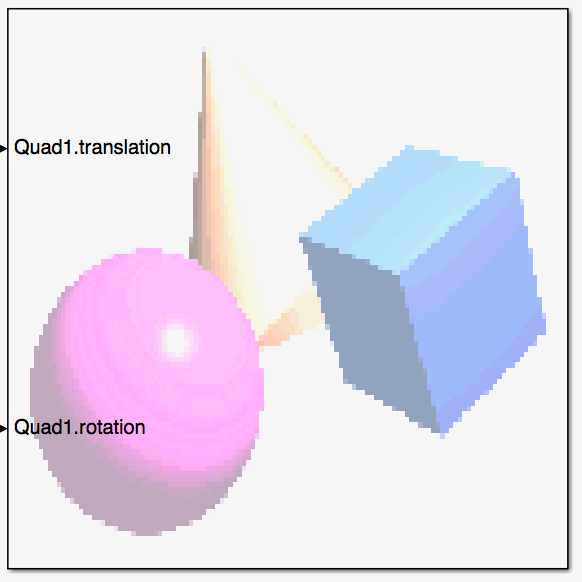

             In this environment, press the play button (Play simulation).

## `Software architecture`

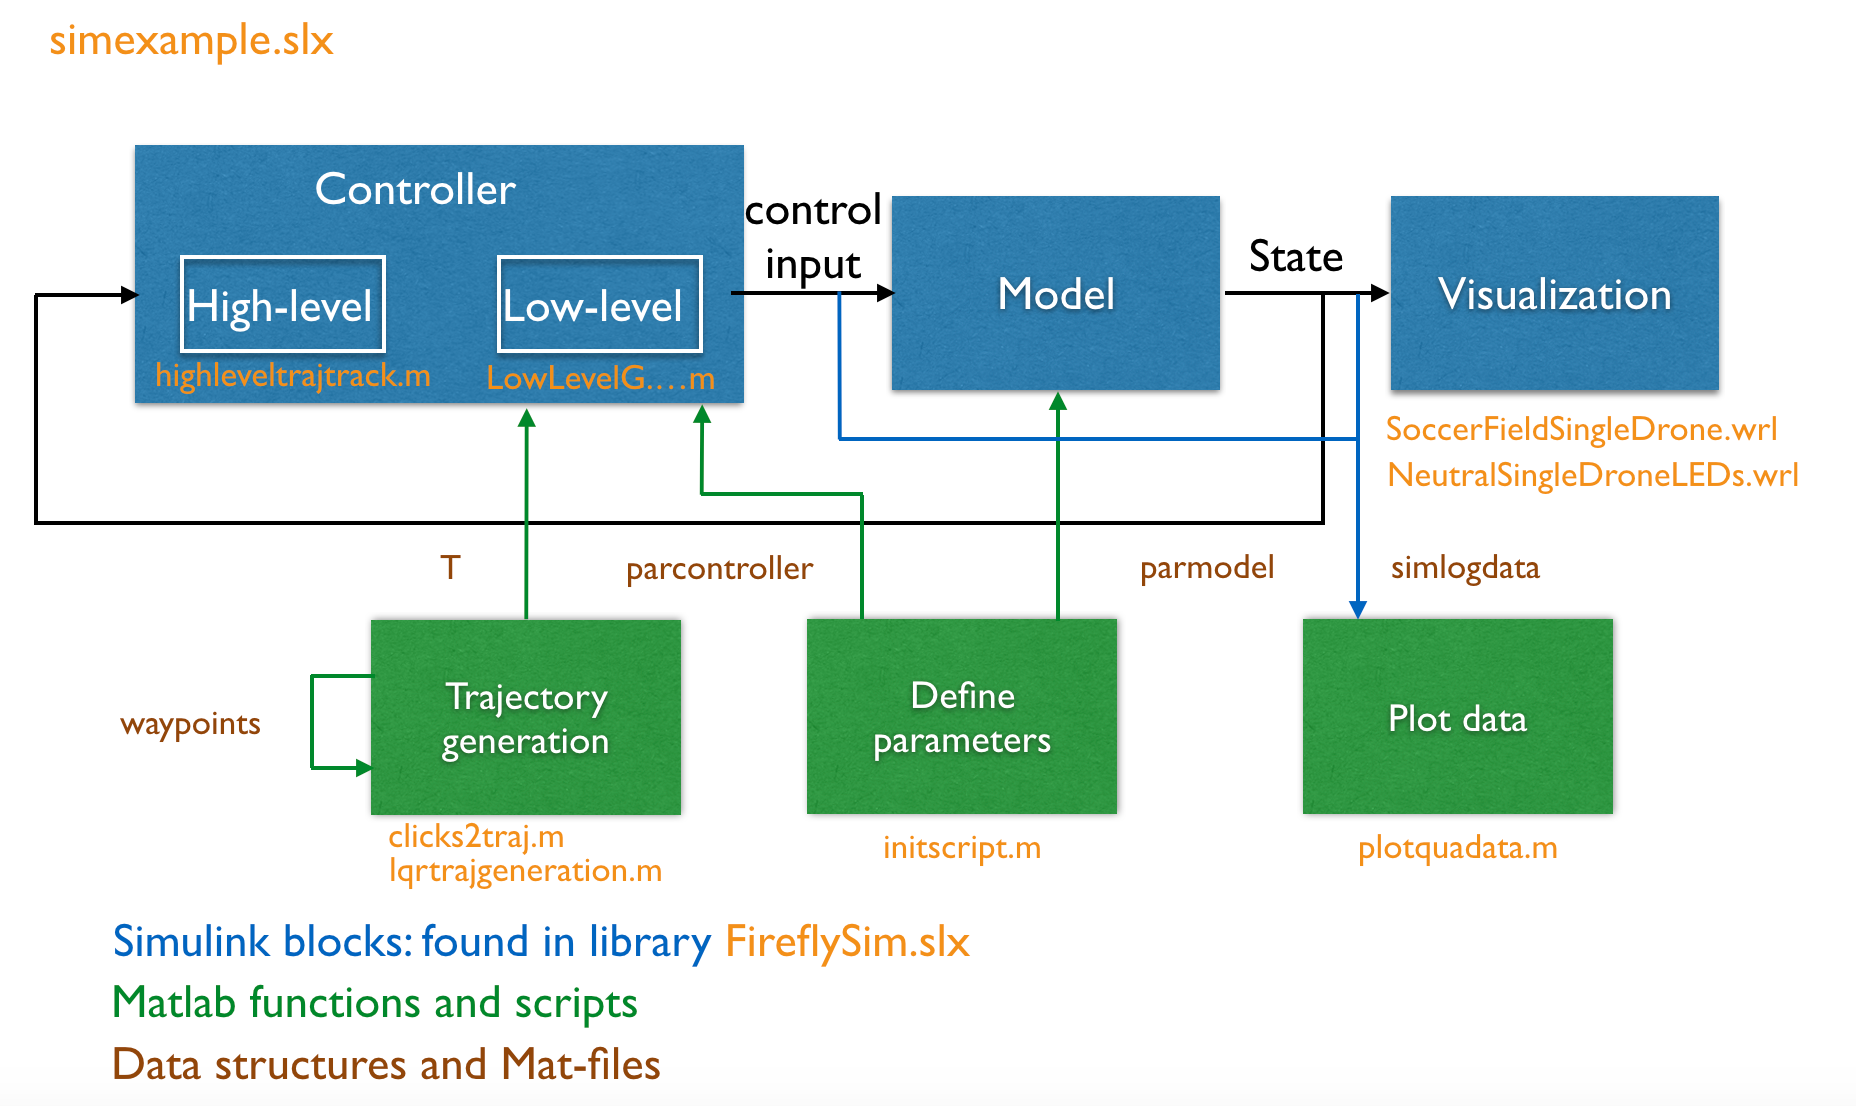

## `Simulink files`

`simexample.slx`

main simulation file integrating the blocks in the library, as shown in the figure below. The log data is simply a block which saves state and input data using a 'to workspace' block.

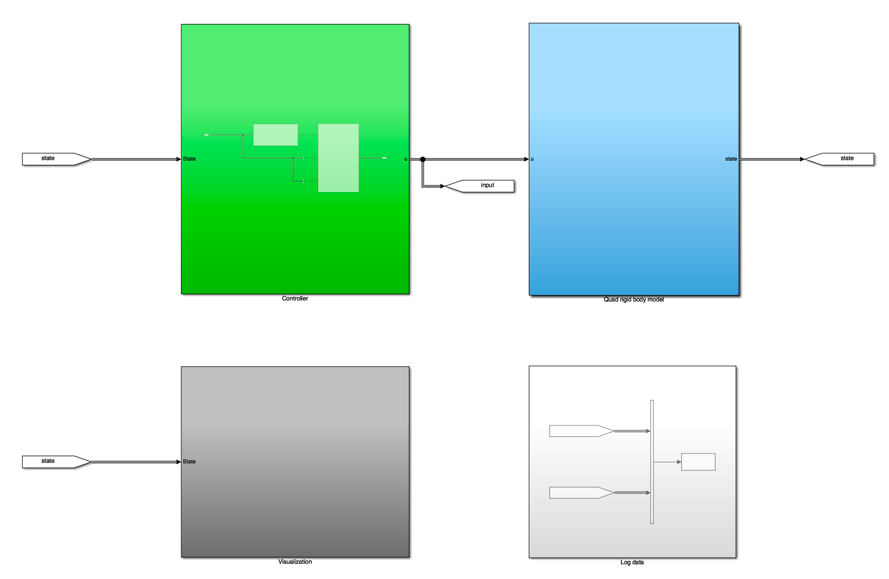

`FireflySimLib.slx`

Library containing three groups of blocks: controllers, quad models, and 3D visualization. 

- controller - In this version just one controller is provided: it provides adequate control actions $u = [ T \, \tau_\phi \, \tau_\theta \, \tau_\psi ]$ comprising overall thurst, and three torques along the rotation axis, given the state $x = [p\, v \, \lambda \, \omega]$ comprising position, velocity, Z-Y-X euler angles and angular velocity.

- quad model. In this version just one model is provided: it outputs the state based on the control input. 

- 3D visualization. Two visualization environments are provided both with just one drone: one mimics the robot soccer field at TU/e and the other is a simple and neutral environment but allows to simulate LEDs. The input to both is simply the state of the quad.

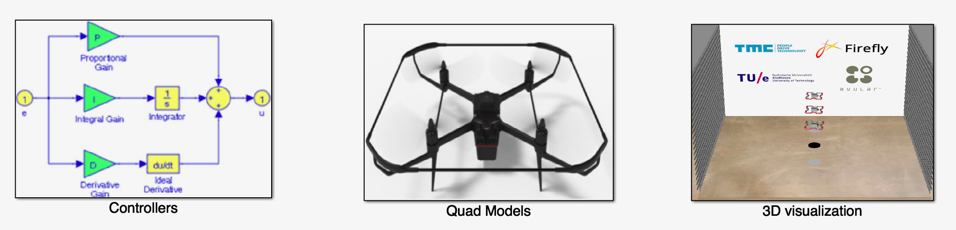

## `Functions and scripts`

`click2traj.m`

Using Matlab built in function getpts.m it starts by asking the user to introduce some points on the image, which for convinience if the image of the soccer field: these points can directly be used by the simulation with the soccer field environment. Click once for introducing points and twice for the final point. This defines the x, and y coordinates. The z and psi coordinates as well as the times at which the drone should reach each way point are defined automatically or can be customized by the user. Many control options allow the user to define this as well as using previously clicked points. After this, it runs the initscript

`lqrtrajgeneration.m`

Uses a dynamic optimization technique (known as linear quadratic regulator - LQR) to provide a smooth trajectory given a set of waypoint in x,y,z and in time, providing also its derivatives up to a user defined order m.

`initscript.m`

loads the trajectory T in T.m generated by clicks2traj, sets the simulation time, and defines the constants which parameterize the controller and the quad model, defined in parcontroller and parmode, respectively. This script is run in the clicks2traj.m but it can also be run independently when a trajectory is alread in T.m.

`plotquadata.m`

distills the information in simlogdata resulting from a simulation to plot the state and input. Control options allow to plot only a subset of the states and inputs.

`highleveltrajtrack.m`

High level control of the quad: sees the quad as a double integrator, receiving 3D position and velocity and outputting acceleration. Standard proportional derivative control law with the option for feedback or not set by flag parcontroller.feedforward.

`LowLevelGeometricController.m`

Low level control of the quad, using a geometrically inspired control technique. It requires as input the desired accelerations coming from an outer loop controller, the euler angles of the quad and the angular velocity. It tries to track these desired accelerations by controlling the quad's thurst vector.

## `MAT-files and Data Stuctures`

`waypoints.mat`

used in clicks2traj.m to save x and y coordinates from a previous trial, so that only z, psi and T coordinates can be twicked.

`T.mat`

Containts the structure T which is used to set the parameters of the reference. This is a crucial structure since it is used for the interface between the Matlab scripts and simulink, in particular to specify the reference to be used in the simulation. Defined in clicks2traj.m

T.X    - X  reference

T.Y    - Y  reference

T.Z    - Z  reference

T.PSI  -  yaw reference

T.VX   - x velocity reference

T.VY   - y velocity reference

T.VZ   - z velocity reference

T.VPSI - yaw velocity reference

T.AX   - x acceleration reference

T.AY   - y acceleration reference

T.AZ   - z acceleration reference

T.APSI - yaw acceleration reference

T.time - discrete-time

T.period - sampling period

`LEDdata.mat`

Contains a data structure to be used in the simulink block 'from workspace'. It is used in visualization environment 'NeutralSingleDroneLEDs.wrl'.

Ledinput1.signals.values is a vector [88×3×N] with 88 vector of 3 RGB values over N time steps according to the sampling period T.period.

`simlogdata`

Data saved in simulink (to Workspace structure) after running the simulation. Used by plotquadata.m to plot state and input variables.

`parmodel`

Data structure created in initscript.m defining the following parameters required by a simulink block in the quadmodel group

parmodel.MomInertia - moment of inertia

parmodel.mass  - mass

parmodel.g - gravity

parmodel.pose0  - initial quad position and yaw

parmodel.cdrag - drag coefficient

`parcontroller`

Data structure created in initscript.m defining the following parameters required by a simulink block in the controller group

parcontroller.k1 - Velocity gain high level trajectory tracking

parcontroller.k2 - Position D gain high level trajectory tracking

parcontroller.k3 - Position P high level trajectory tracking

parcontroller.kpsi - gain for psi control low level control

parcontroller.ktauxy  - gain for rz control low level control

parcontroller.satT - Thurst saturation 

parcontroller.feedforward - 1 use feedforward, 0 do not

## `Other Files`

`SoccerFieldSingleDrone.wrl`

One of the virtual reality environments used for the visualization block. Contains one single drone in a soccer fields.

`NeutralSingleDroneLEDs.wrl`

One of the virtual reality environments used for the visualization block.

## Other comments

In version 1.1, one expects:

- The soccer field environment to exactly match the dimensions of the TU/e soccer field at TU/e.

- An improved drone in the visualization environment.

- Visualization environment with moving cameras.

- Improved quadcopter models including for instance drag.

- Replacing the clicks2traj.m by integrating a javascript app.

- Instructions on the team's workflow, documentation policy, and sharing files policy.